clear 
close all 
clc

% Defining PID controllers to be used in the Analysis
R_phi_mc = tunablePID('R_phi_mc','P')

R_phi_mc =   Tunable continuous-time PID controller "R_phi_mc" with formula:

 
  Kp
 

  and tunable parameters Kp.

Type "pid(R_phi_mc)" to see the current value and "get(R_phi_mc)" to see all properties.


R_phi_mc.Kp.Value = 8.64;          

R_p_mc = tunablePID2('R_p','PID')

R_p_mc =   Tunable continuous-time 2-DOF PID controller "R_p" with equation:

                       1                s    
  u = Kp (b*r-y) + Ki --- (r-y) + Kd -------- (c*r-y)
                       s              Tf*s+1 

  where r,y are the controller inputs and Kp, Ki, Kd, Tf, b, c are tunable gains.

Type "pid2(R_p_mc)" to see the current value and "get(R_p_mc)" to see all properties.


R_p_mc.Kp.Value = 0.399;              
R_p_mc.Ki.Value = 1.05;              
R_p_mc.Kd.Value = -4.38e-8;   
R_p_mc.c.Value = 0;
R_p_mc.c.Free = false;    
R_p_mc.b.Value = 1;
R_p_mc.b.Free = false;
R_p_mc.Tf.Value = 0.01;
R_p_mc.Tf.Free = false;

R_p_pid = tf(R_p_mc(1))

R_p_pid =
 
  0.399 s + 1.05
  --------------
        s
 
Name: R_p
Continuous-time transfer function.



R_phi_pid = tf(R_phi_mc)

R_phi_pid =
 
  8.64
 
Name: R_phi_mc
Static gain.



g = 9.81;

integrator=tf(1,[1 0]);

N=500;

for n= 1:N
   n,      
    
    % Defining system derivatives using uncertainty ranges
    Y_v_mc(n) = normrnd(-0.1068,0.1068*3*4.26/100);  
    Y_p_mc(n) = normrnd(0.1192,0.1068*3*2.03/100);
    L_v_mc(n) = normrnd(-5.9755,5.9755*3*1.83/100);
    L_p_mc(n) = normrnd(-2.6478,2.6478*3*2.01/100);
    
    Y_d_mc(n) = normrnd(-10.1647,10.1647*3*1.37/100);
    L_d_mc(n) = normrnd(450.7085,450.7085*3*0.81/100);
    
    A_mc{n} = [Y_v_mc(n) Y_p_mc(n) g; L_v_mc(n) L_p_mc(n) 0; 0 1 0];
    B_mc{n} = [Y_d_mc(n) L_d_mc(n) 0]';
    C_mc    = [0 1 0; 0 0 1];
    D_mc    = [0 0]';
    
    G_mc{n} = ss(A_mc{n},B_mc{n},C_mc,D_mc);
    G_mc_tf{n} = tf(G_mc{n}); 
    
    % Defining the F and S of the inner loop
    F_1(n) = minreal((R_p_pid*G_mc_tf{n}(1))/(1+R_p_pid*G_mc_tf{n}(1)));
    S_1(n) = 1 - F_1(n);
    
    % Defining the F and S of the outer loop
    F_2(n) = minreal((integrator*F_1(n)*R_phi_pid)/(1+integrator*F_1(n)*R_phi_pid));
    S_2(n) = 1-F_2(n);
    
    % Gain and Phase Margin
    [Gm(n),Pm(n)] = margin(minreal((integrator*F_1(n)*R_phi_pid))); 
    
    t=(0:0.01:10);
    
    y=step(F_2(n),t);
    S_mc = stepinfo(y,t,1);

    % Settling Time and Overshoot
    Sett(n)=S_mc.SettlingTime;
    Over(n)=S_mc.Overshoot;
end

n = 1

n = 2

n = 3

n = 4

n = 5

n = 6

n = 7

n = 8

n = 9

n = 10

n = 11

n = 12

n = 13

n = 14

n = 15

n = 16

n = 17

n = 18

n = 19

n = 20

n = 21

n = 22

n = 23

n = 24

n = 25

n = 26

n = 27

n = 28

n = 29

n = 30

n = 31

n = 32

n = 33

n = 34

n = 35

n = 36

n = 37

n = 38

n = 39

n = 40

n = 41

n = 42

n = 43

n = 44

n = 45

n = 46

n = 47

n = 48

n = 49

n = 50

n = 51

n = 52

n = 53

n = 54

n = 55

n = 56

n = 57

n = 58

n = 59

n = 60

n = 61

n = 62

n = 63

n = 64

n = 65

n = 66

n = 67

n = 68

n = 69

n = 70

n = 71

n = 72

n = 73

n = 74

n = 75

n = 76

n = 77

n = 78

n = 79

n = 80

n = 81

n = 82

n = 83

n = 84

n = 85

n = 86

n = 87

n = 88

n = 89

n = 90

n = 91

n = 92

n = 93

n = 94

n = 95

n = 96

n = 97

n = 98

n = 99

n = 100

n = 101

n = 102

n = 103

n = 104

n = 105

n = 106

n = 107

n = 108

n = 109

n = 110

n = 111

n = 112

n = 113

n = 114

n = 115

n = 116

n = 117

n = 118

n = 119

n = 120

n = 121

n = 122

n = 123

n = 124

n = 125

n = 126

n = 127

n = 128

n = 129

n = 130

n = 131

n = 132

n = 133

n = 134

n = 135

n = 136

n = 137

n = 138

n = 139

n = 140

n = 141

n = 142

n = 143

n = 144

n = 145

n = 146

n = 147

n = 148

n = 149

n = 150

n = 151

n = 152

n = 153

n = 154

n = 155

n = 156

n = 157

n = 158

n = 159

n = 160

n = 161

n = 162

n = 163

n = 164

n = 165

n = 166

n = 167

n = 168

n = 169

n = 170

n = 171

n = 172

n = 173

n = 174

n = 175

n = 176

n = 177

n = 178

n = 179

n = 180

n = 181

n = 182

n = 183

n = 184

n = 185

n = 186

n = 187

n = 188

n = 189

n = 190

n = 191

n = 192

n = 193

n = 194

n = 195

n = 196

n = 197

n = 198

n = 199

n = 200

n = 201

n = 202

n = 203

n = 204

n = 205

n = 206

n = 207

n = 208

n = 209

n = 210

n = 211

n = 212

n = 213

n = 214

n = 215

n = 216

n = 217

n = 218

n = 219

n = 220

n = 221

n = 222

n = 223

n = 224

n = 225

n = 226

n = 227

n = 228

n = 229

n = 230

n = 231

n = 232

n = 233

n = 234

n = 235

n = 236

n = 237

n = 238

n = 239

n = 240

n = 241

n = 242

n = 243

n = 244

n = 245

n = 246

n = 247

n = 248

n = 249

n = 250

n = 251

n = 252

n = 253

n = 254

n = 255

n = 256

n = 257

n = 258

n = 259

n = 260

n = 261

n = 262

n = 263

n = 264

n = 265

n = 266

n = 267

n = 268

n = 269

n = 270

n = 271

n = 272

n = 273

n = 274

n = 275

n = 276

n = 277

n = 278

n = 279

n = 280

n = 281

n = 282

n = 283

n = 284

n = 285

n = 286

n = 287

n = 288

n = 289

n = 290

n = 291

n = 292

n = 293

n = 294

n = 295

n = 296

n = 297

n = 298

n = 299

n = 300

n = 301

n = 302

n = 303

n = 304

n = 305

n = 306

n = 307

n = 308

n = 309

n = 310

n = 311

n = 312

n = 313

n = 314

n = 315

n = 316

n = 317

n = 318

n = 319

n = 320

n = 321

n = 322

n = 323

n = 324

n = 325

n = 326

n = 327

n = 328

n = 329

n = 330

n = 331

n = 332

n = 333

n = 334

n = 335

n = 336

n = 337

n = 338

n = 339

n = 340

n = 341

n = 342

n = 343

n = 344

n = 345

n = 346

n = 347

n = 348

n = 349

n = 350

n = 351

n = 352

n = 353

n = 354

n = 355

n = 356

n = 357

n = 358

n = 359

n = 360

n = 361

n = 362

n = 363

n = 364

n = 365

n = 366

n = 367

n = 368

n = 369

n = 370

n = 371

n = 372

n = 373

n = 374

n = 375

n = 376

n = 377

n = 378

n = 379

n = 380

n = 381

n = 382

n = 383

n = 384

n = 385

n = 386

n = 387

n = 388

n = 389

n = 390

n = 391

n = 392

n = 393

n = 394

n = 395

n = 396

n = 397

n = 398

n = 399

n = 400

n = 401

n = 402

n = 403

n = 404

n = 405

n = 406

n = 407

n = 408

n = 409

n = 410

n = 411

n = 412

n = 413

n = 414

n = 415

n = 416

n = 417

n = 418

n = 419

n = 420

n = 421

n = 422

n = 423

n = 424

n = 425

n = 426

n = 427

n = 428

n = 429

n = 430

n = 431

n = 432

n = 433

n = 434

n = 435

n = 436

n = 437

n = 438

n = 439

n = 440

n = 441

n = 442

n = 443

n = 444

n = 445

n = 446

n = 447

n = 448

n = 449

n = 450

n = 451

n = 452

n = 453

n = 454

n = 455

n = 456

n = 457

n = 458

n = 459

n = 460

n = 461

n = 462

n = 463

n = 464

n = 465

n = 466

n = 467

n = 468

n = 469

n = 470

n = 471

n = 472

n = 473

n = 474

n = 475

n = 476

n = 477

n = 478

n = 479

n = 480

n = 481

n = 482

n = 483

n = 484

n = 485

n = 486

n = 487

n = 488

n = 489

n = 490

n = 491

n = 492

n = 493

n = 494

n = 495

n = 496

n = 497

n = 498

n = 499

n = 500

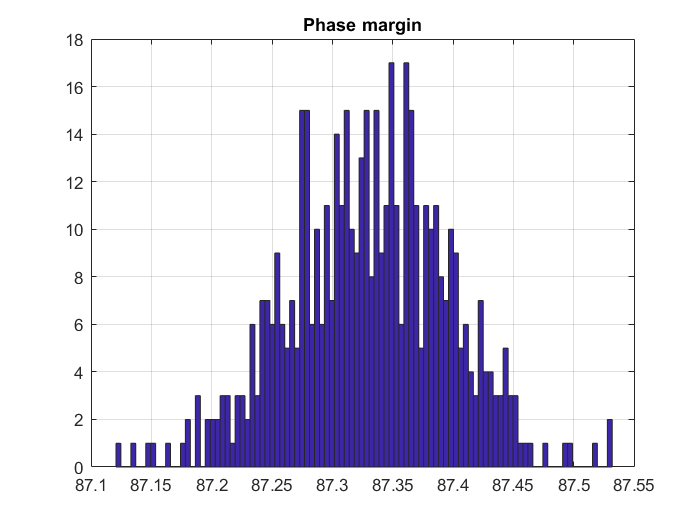


figure(6),hist(Pm,100), grid, title('Phase margin')

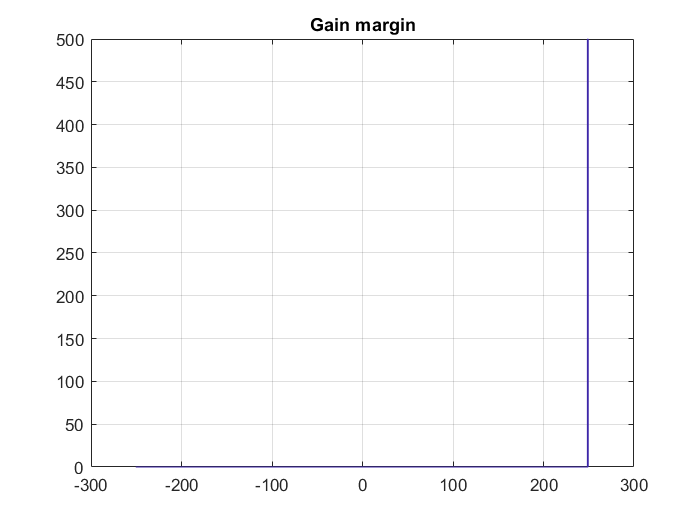


figure(7),hist(Gm,500), grid, title('Gain margin')

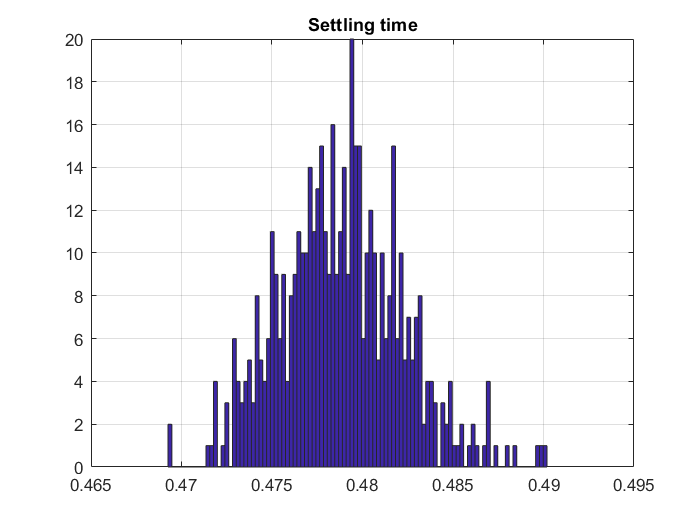


figure(8),hist(Sett,100), grid, title('Settling time')

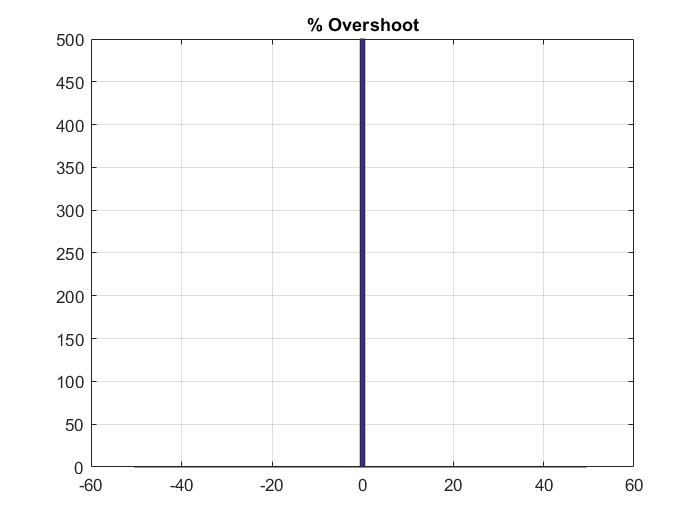


figure(9),hist(Over,100), grid, title('% Overshoot')